# **Introductory script illustrating aspects of the TreeShrew optics**

#### **See also**: 

*Copyright: Nicolas P. Cottaris,  ISETBio Team,, 2018*

# OUTLINE

 **   Step 1.** Generate different treeshrew optics models

 **   Step 2.** Generate a test stimulus (1 c/deg Gabor) as rendered on a presentation display

**    Step 3.** Generate and compare retinal images for the different threeshrew optics models

- default optics

- large PSF

- double focal length, but same PSF in angular size  

- double focal length, double pupil diameter      

**    Step 4.** Compare retinal illuminance levels for the different optics models

# **Step 1a.** Generate TreeShrew optics with default params

### Initialize the default optics and plot some aspects

The default optics is based on a Gaussian Point Spead Function (PSF)  with a 20 micron sigma.

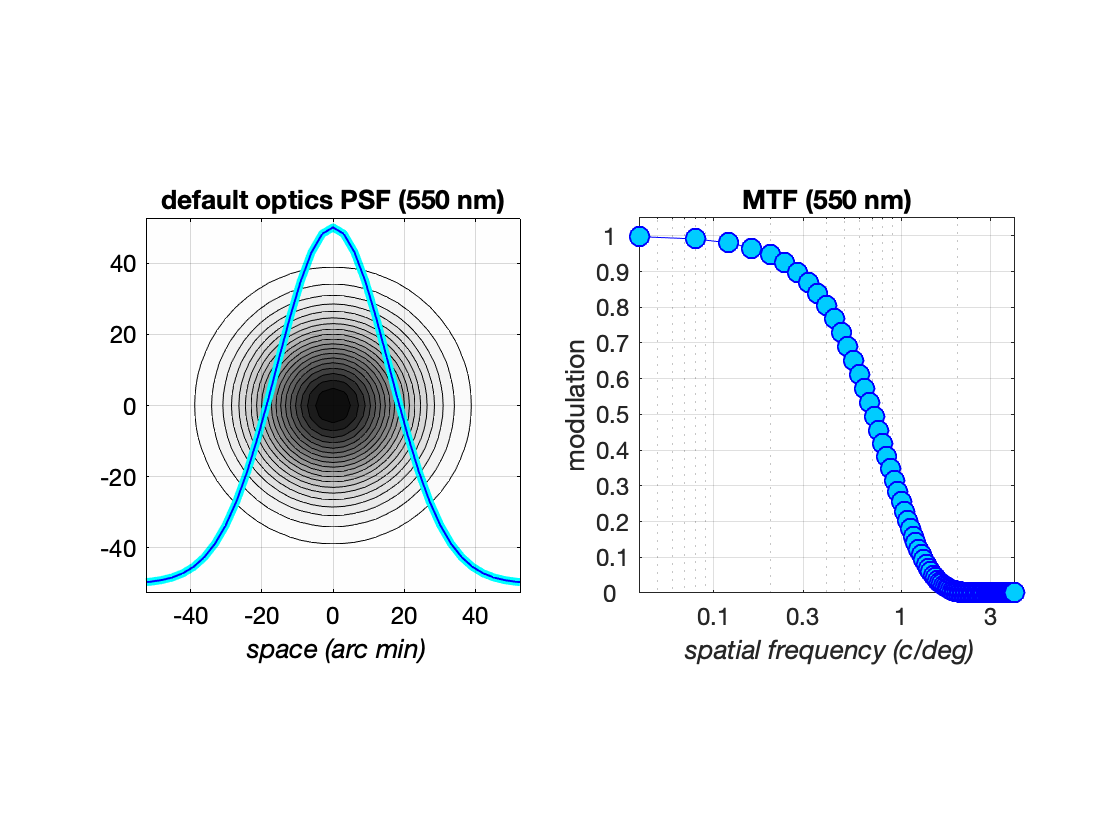

% Default tree shew optics
theDefaultOI = oiTreeShrewCreate('name', 'default optics');

% Visualize the PSF at 550 nm
visualizedSpatialSupportArcMin = 100;
visualizedSpatialSfrequencyCPD = 4.0;
visualizeOptics(theDefaultOI, 550, ...
    visualizedSpatialSupportArcMin, ...
    visualizedSpatialSfrequencyCPD);

# **Step 1b.** Generate custom TreeShrew optics with a large PSF (40 micron PSF)

### Set a 40$\mu m$ sigma PSF

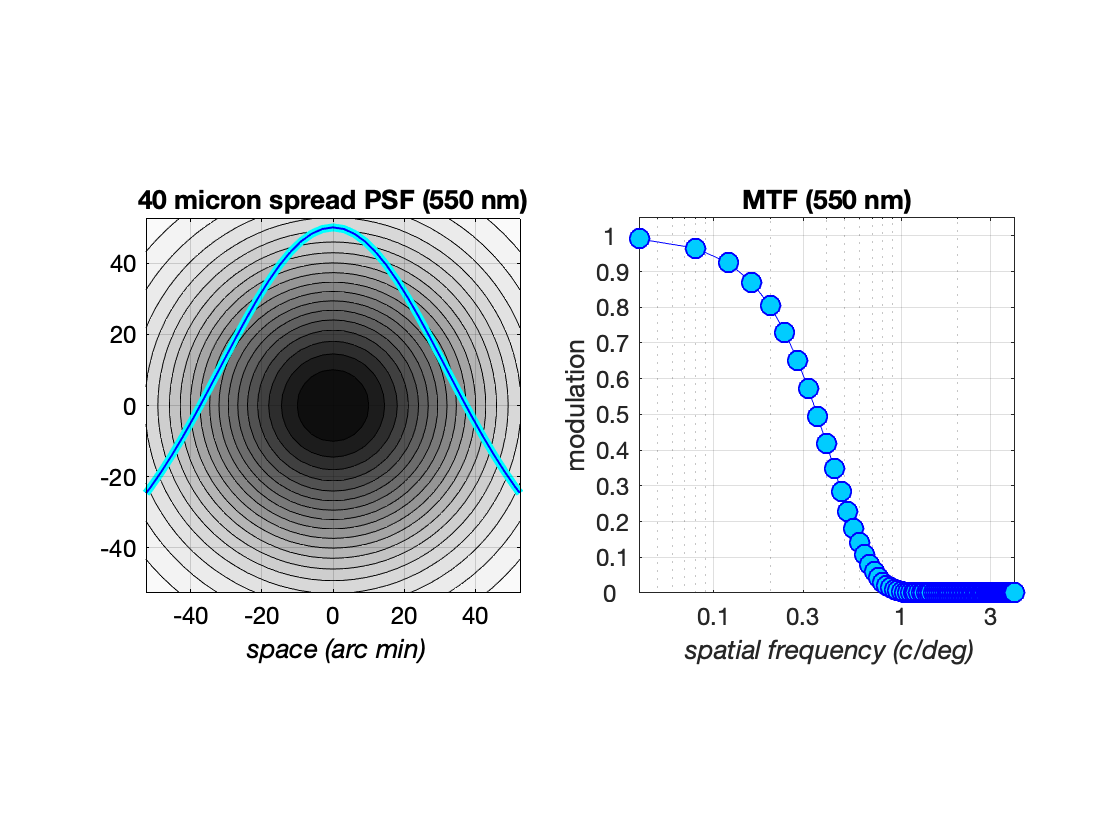

% Custom sigma tree shew optics 
theBlurredOI = oiTreeShrewCreate(...
    'name', '40 micron spread', ...
    'inFocusPSFsigmaMicrons', 40 ... % 40 microns
);

% Visualize the PSF/OTF at 550 nm
visualizeOptics(theBlurredOI, 550, ...
    visualizedSpatialSupportArcMin, ...
    visualizedSpatialSfrequencyCPD);

# **Step 1c.** Generate custom TreeShrew optics with longer focal length (but same PSF spread in arc min)

### Double the focal length (default is 4.35 mm) and also double the PSF sigma, so as to have the same PSF in arc min

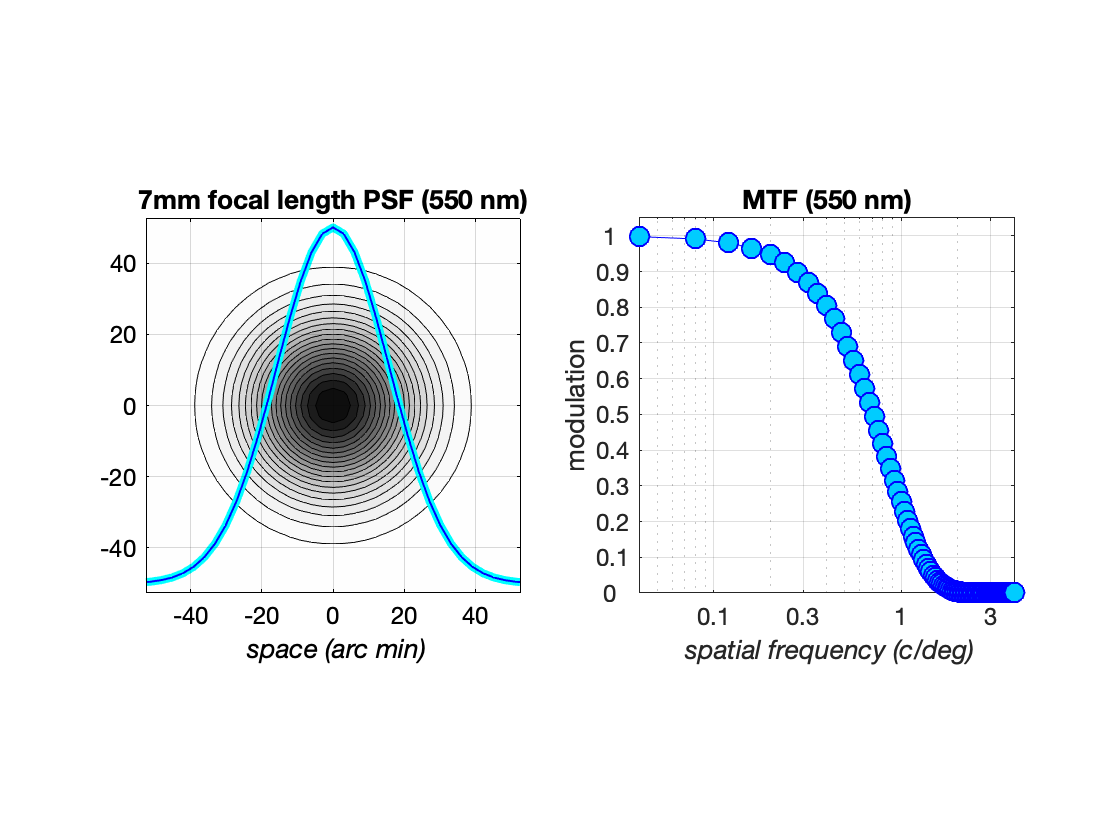

% Custom focal length tree shew optics 
theLongerFocalLengthOI = oiTreeShrewCreate(...
    'name', '7mm focal length', ...
    'focalLengthMM', 4.35*2, ... 
    'inFocusPSFsigmaMicrons', 20*2 ...
);
% Visualize the PSF/OTF at 550 nm
visualizeOptics(theLongerFocalLengthOI, 550, ...
    visualizedSpatialSupportArcMin, ...
    visualizedSpatialSfrequencyCPD);

# **Step 1d.** Generate custom TreeShrew optics with longer focal length (same PSF spread in arc min), and double the pupil size

### Double the focal length (default is 4.35 mm) and the PSF sigma, and also double in pupil diameter. 

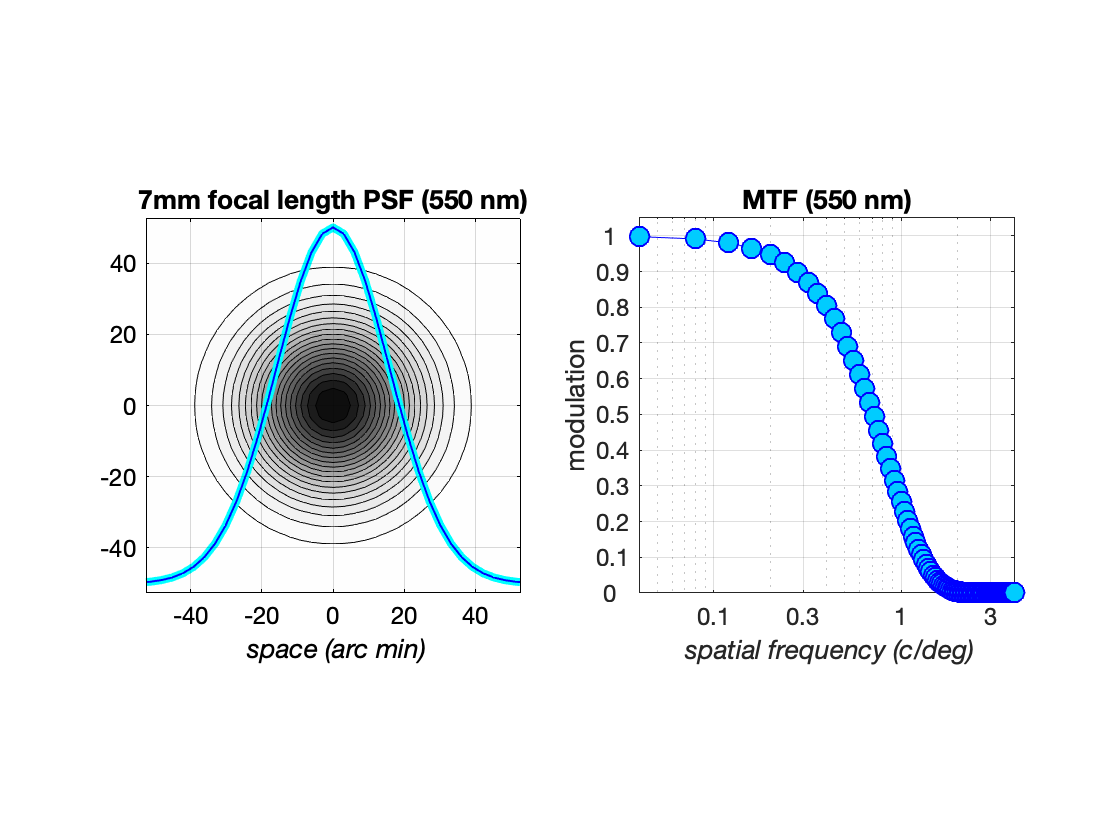

% Custom focal length tree shew optics 
theLongerFocalLengthWidePupilOI = oiTreeShrewCreate(...
    'name', '7mm focal length', ...
    'focalLengthMM', 4.35*2, ... 
    'inFocusPSFsigmaMicrons', 20*2, ...
    'pupilDiameterMM', 4*2 ...
);
% Visualize the PSF/OTF at 550 nm
visualizeOptics(theLongerFocalLengthWidePupilOI, 550, ...
    visualizedSpatialSupportArcMin, ...
    visualizedSpatialSfrequencyCPD);

# **Step 2.** Generate a test stimulus (1 c/deg Gabor) as rendered on a presentation display

%% Create presentation display and place it 5 cm in front of the eye
presentationDisplay = displayCreate('LCD-Apple', 'viewing distance', 5/100);

%% 1 c/deg Gabor stimulus 
stimParams = struct(...
    'spatialFrequencyCyclesPerDeg', 0.7, ... % 0.7 cycles/deg
    'orientationDegs', 0, ...               % 0 degrees
    'phaseDegs', 90, ...                    % spatial phase degrees
    'sizeDegs', 5.0, ...                    % 5 x 5 size
    'sigmaDegs', 0.8, ...                   % sigma of Gaussian envelope
    'contrast', 0.9,...                     % 0.9 Michelson contrast
    'meanLuminanceCdPerM2', 40, ...         % 40 cd/m2 mean luminance
    'pixelsAlongWidthDim', [], ...          % pixels- width dimension
    'pixelsAlongHeightDim', [] ...          % pixel- height dimension
    );


% Generate a scene representing the Gabor stimulus with the above params as
% realized on the presentationDisplay
realizedStimulusScene = generateGaborScene(...
    'stimParams', stimParams,...
    'presentationDisplay', presentationDisplay);

sceneGet(realizedStimulusScene, 'size')

ans =    528   528


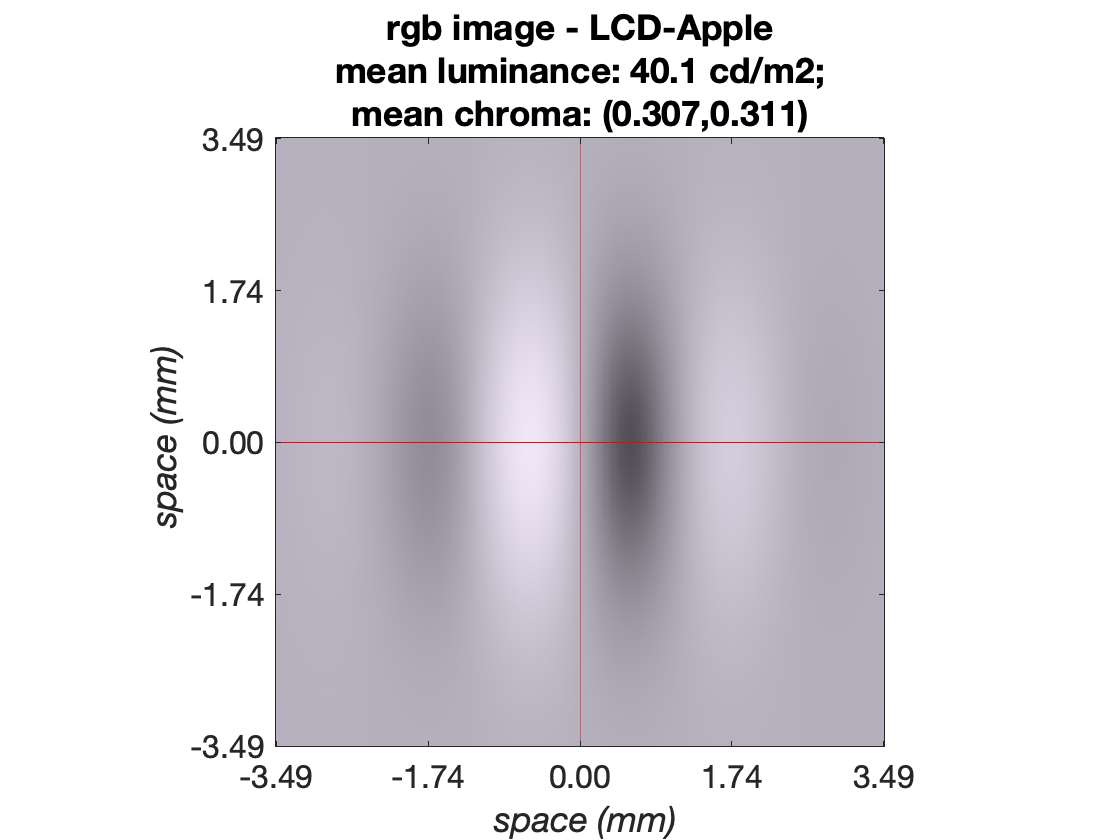

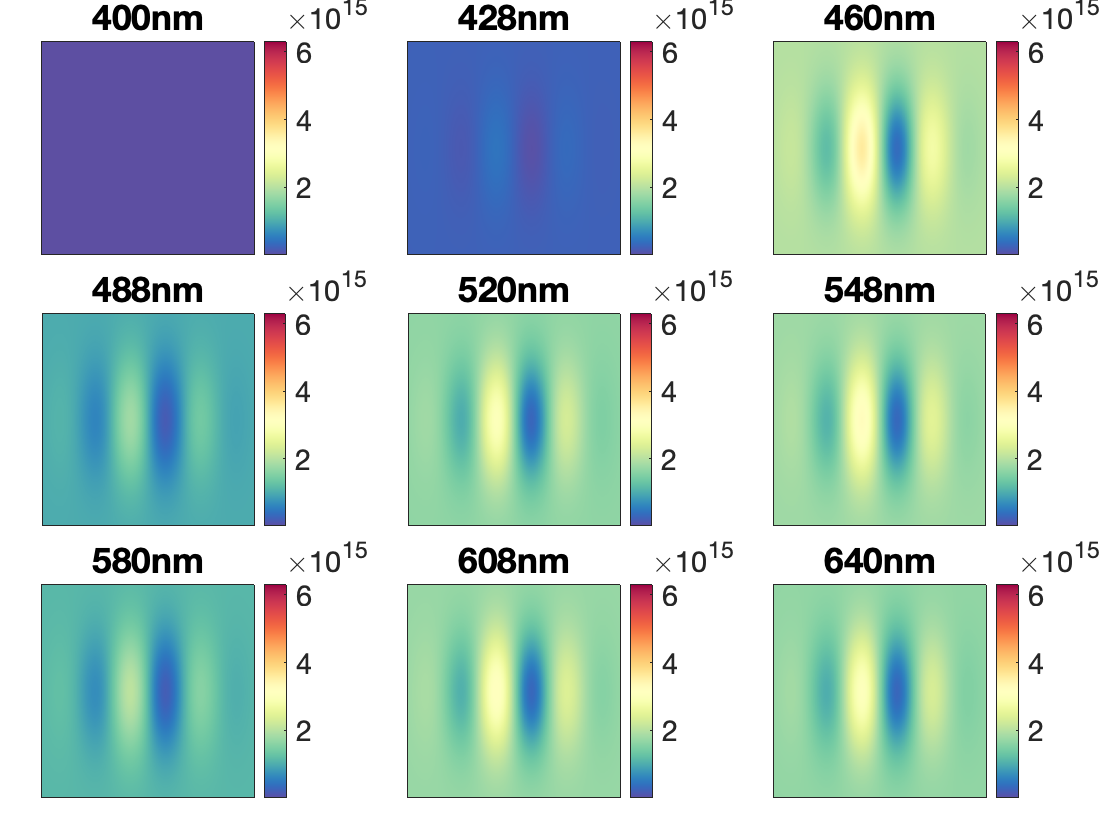

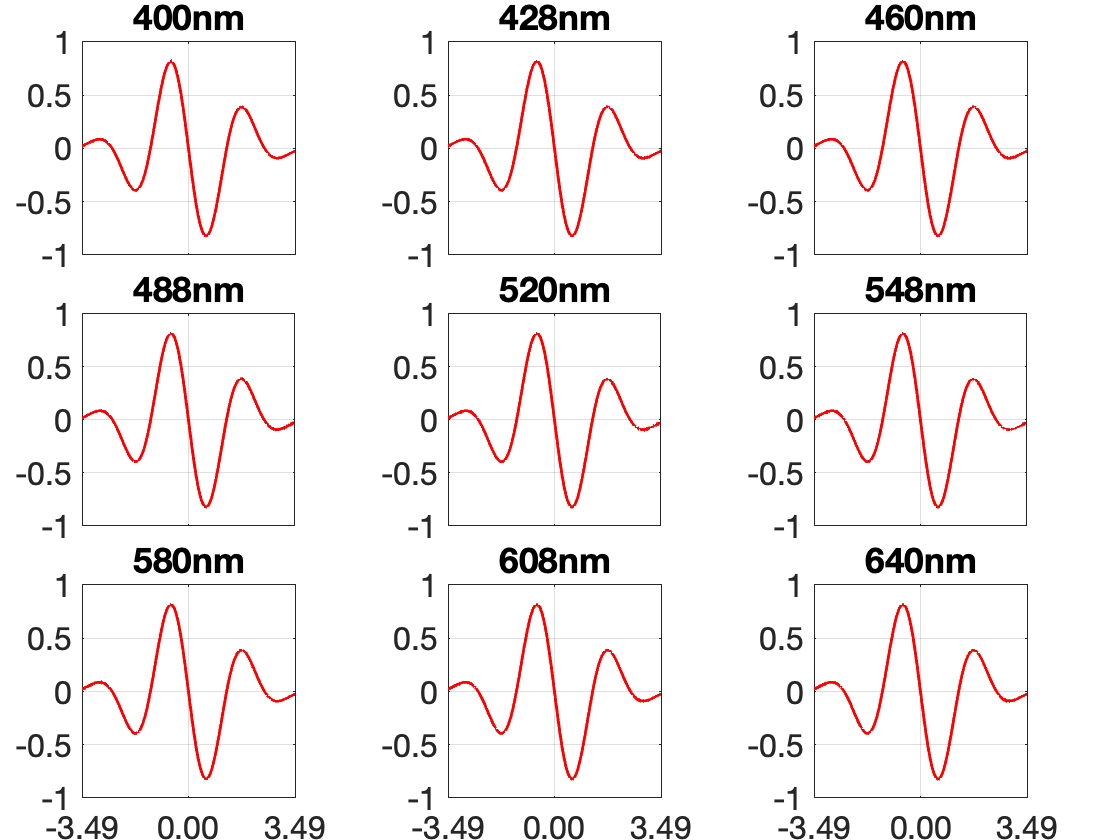

% Visualize different aspects of the generated scene
visualizeScene(realizedStimulusScene, 'displayContrastProfiles', true);

# **Step 4.** Generate retinal images for the different optics models

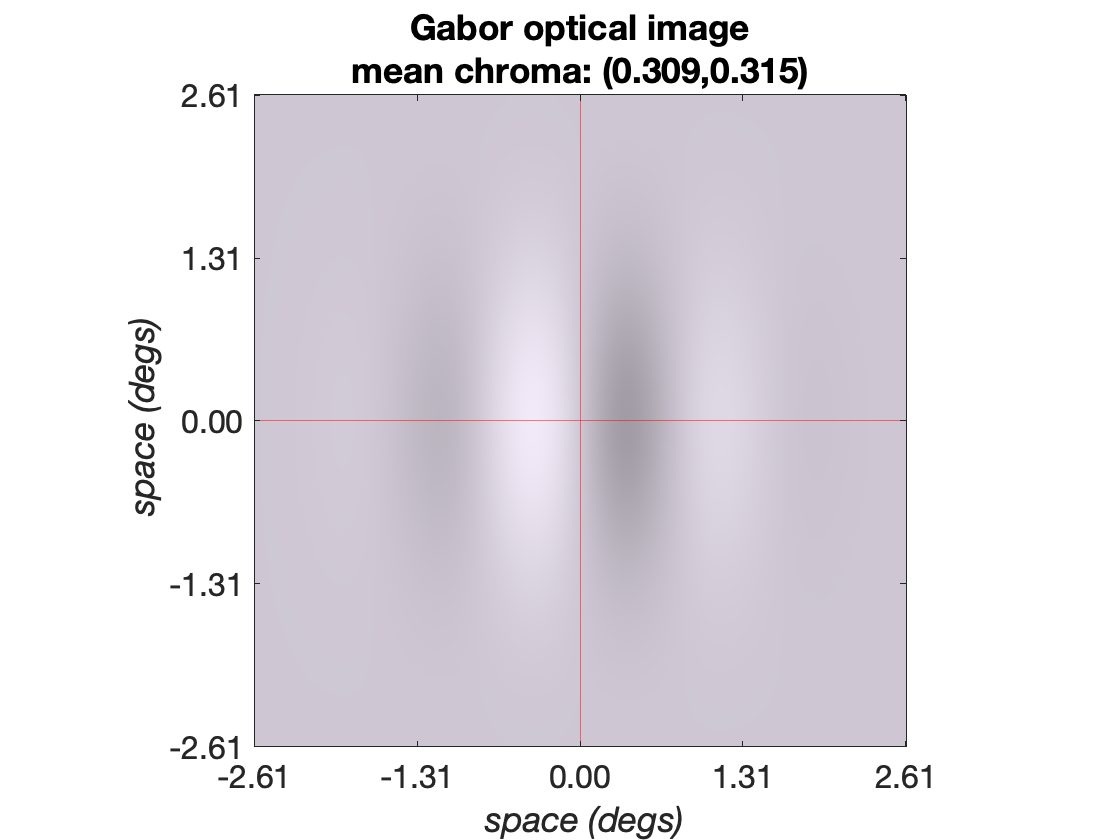

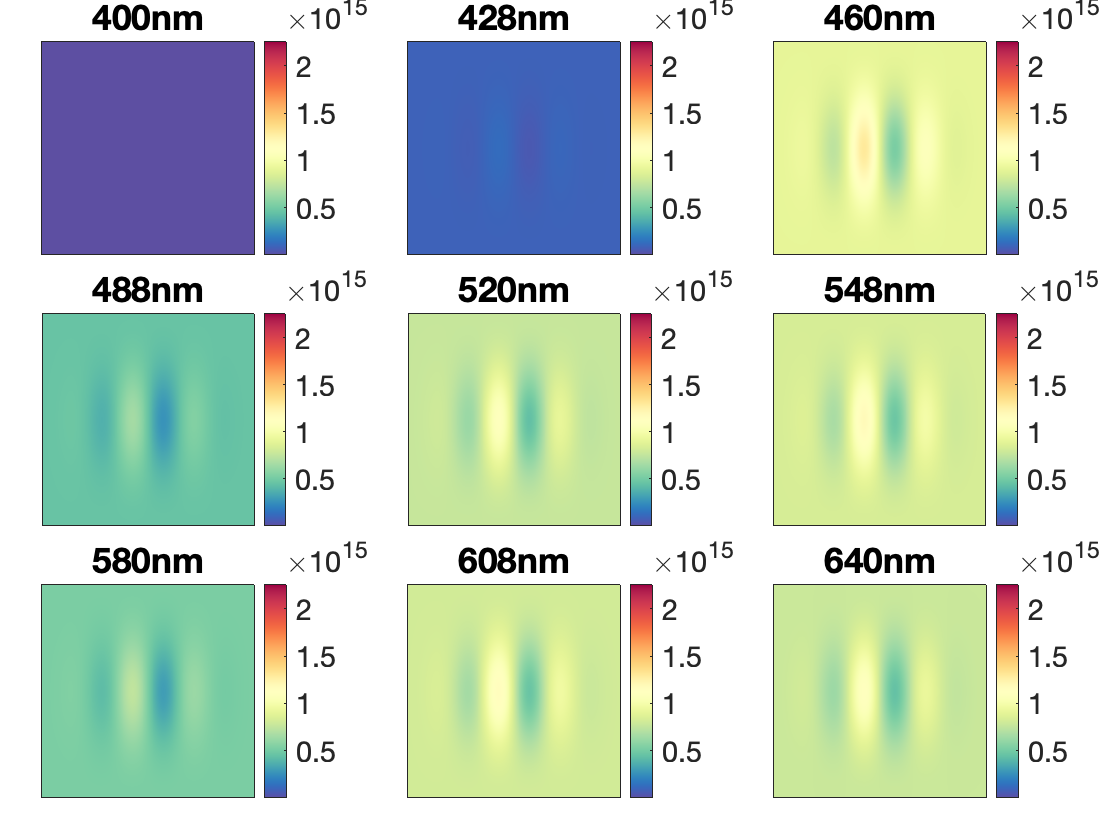

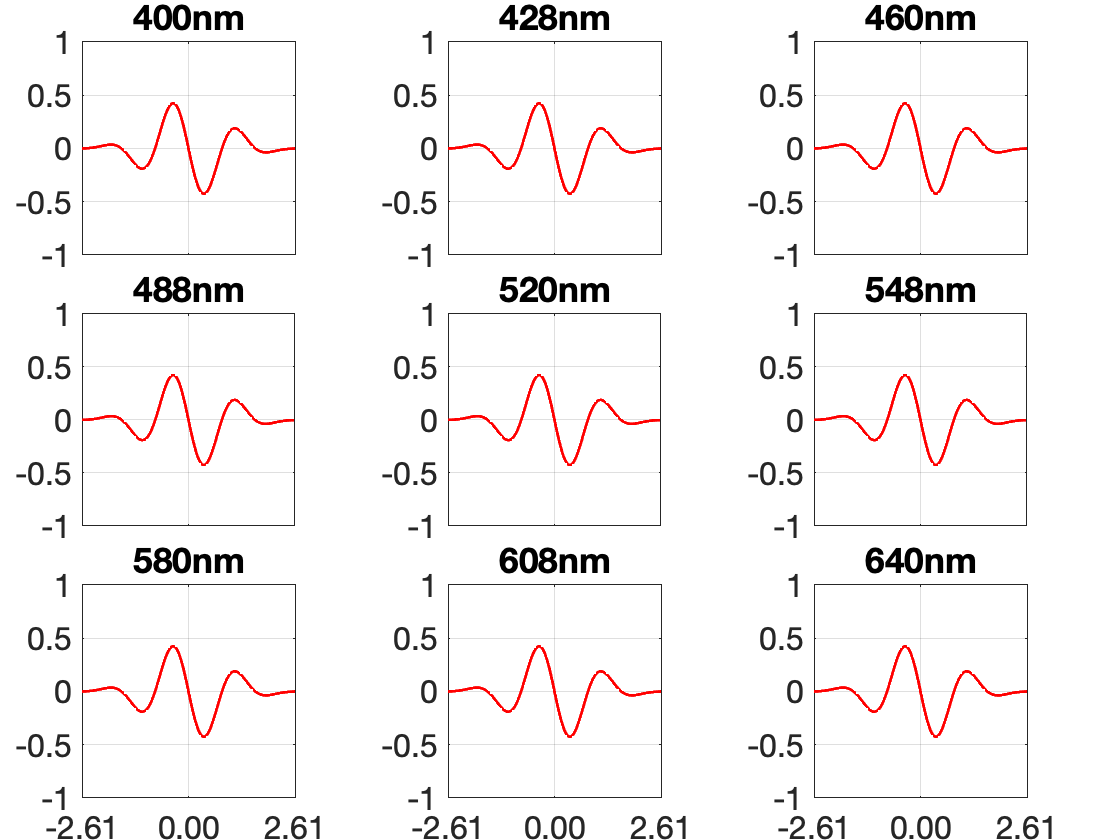

%% Compute the retinal image for the default optics
theDefaultOI = oiCompute(theDefaultOI, realizedStimulusScene);

%% Visualize different aspects of the computed optical image
visualizeOpticalImage(theDefaultOI, 'displayRetinalContrastProfiles', true);

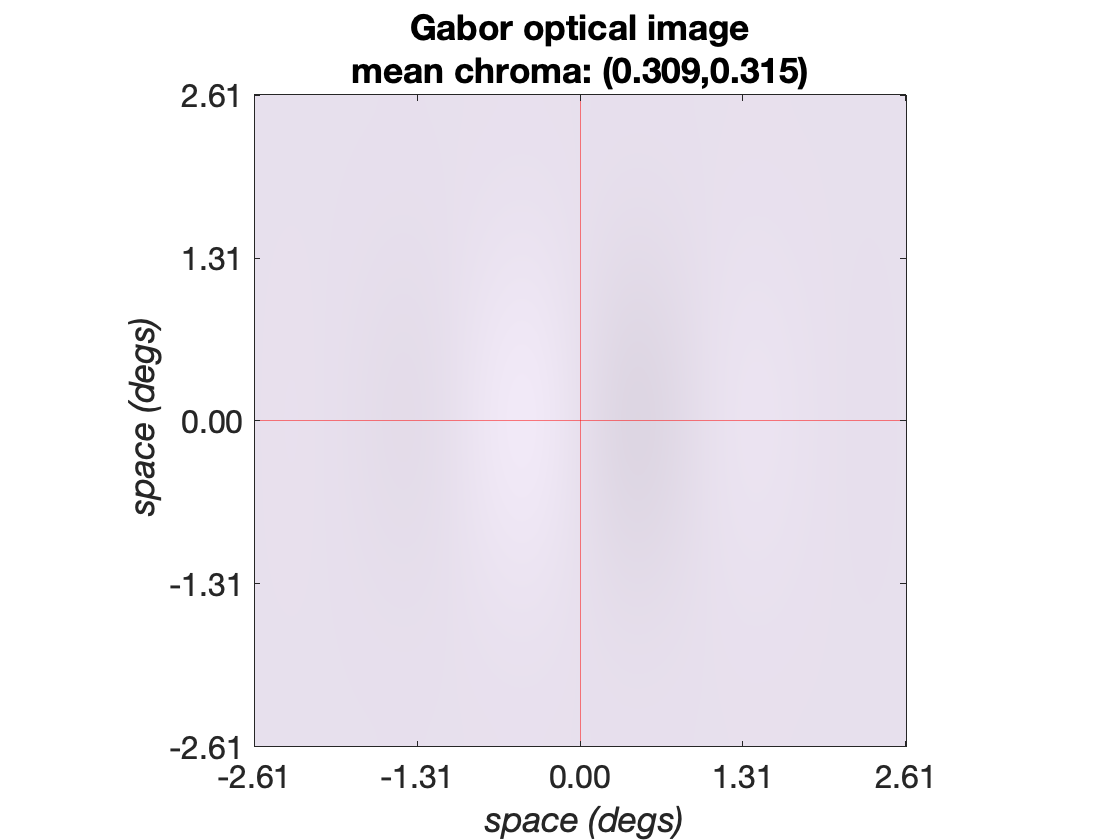

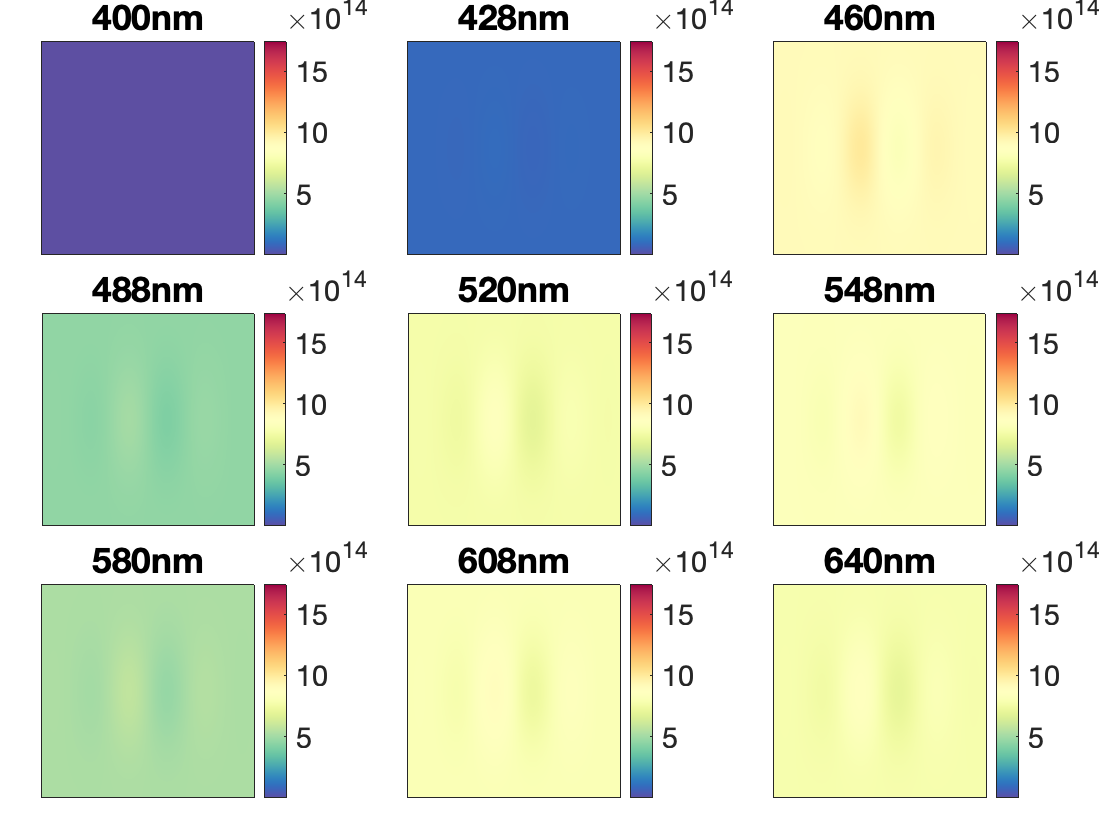

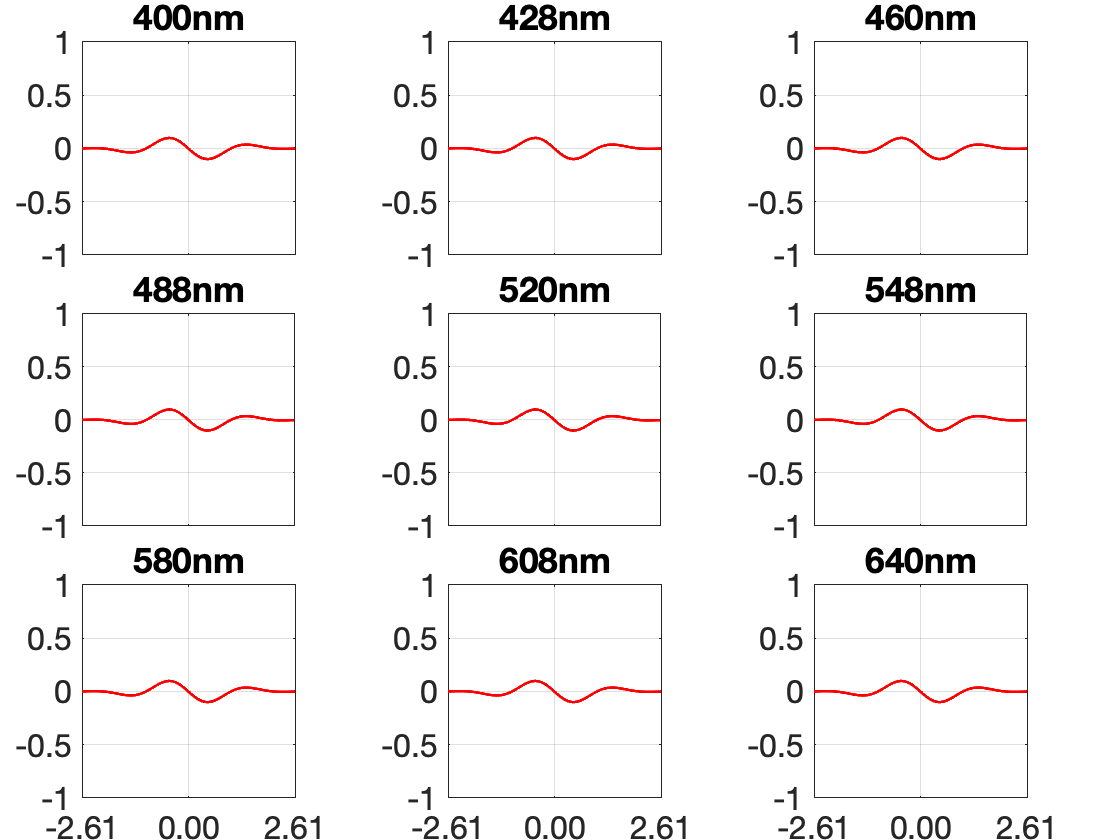

%% Compute the retinal image for the blurred optics
theBlurredOI = oiCompute(theBlurredOI, realizedStimulusScene);

%% Visualize different aspects of the computed optical image
visualizeOpticalImage(theBlurredOI, 'displayRetinalContrastProfiles', true);

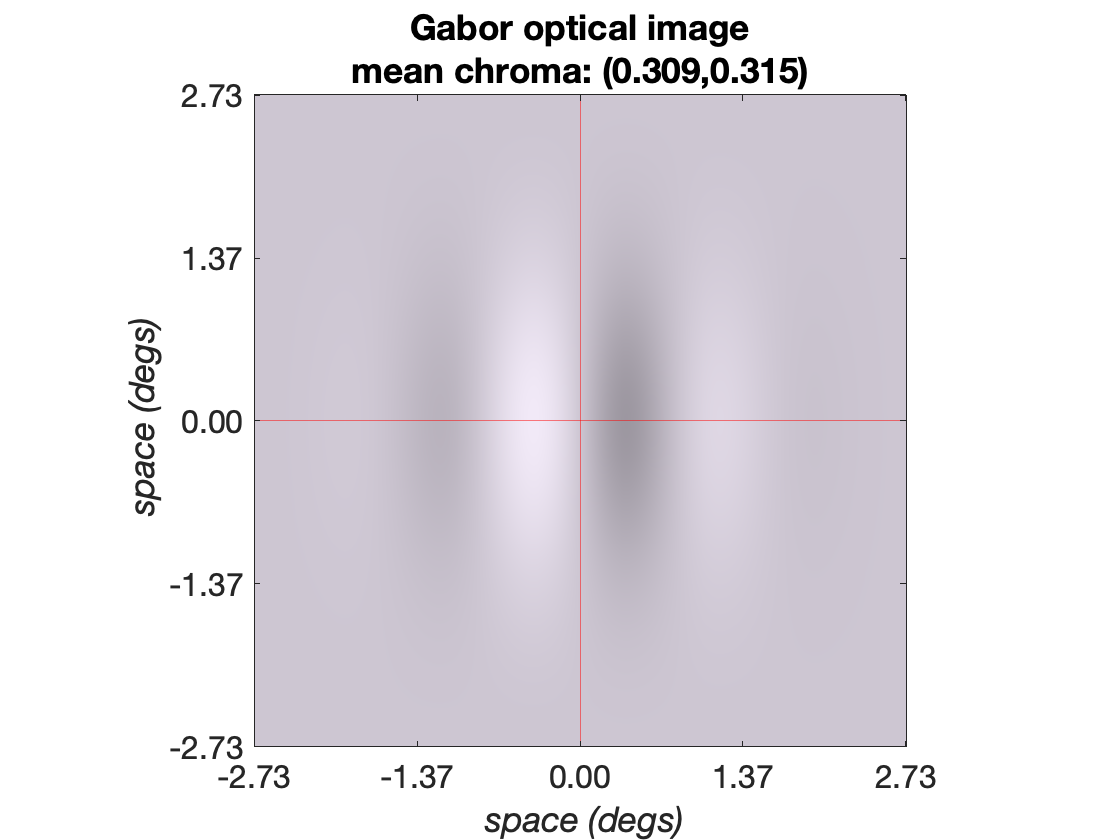

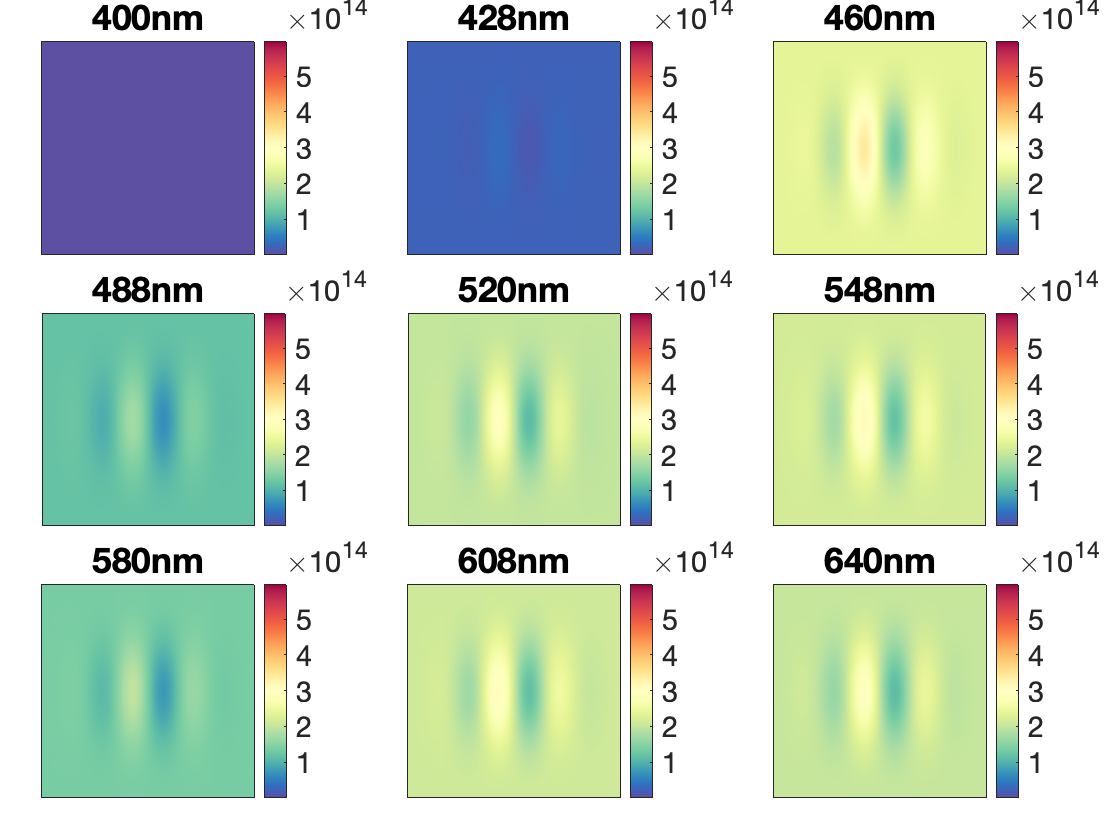

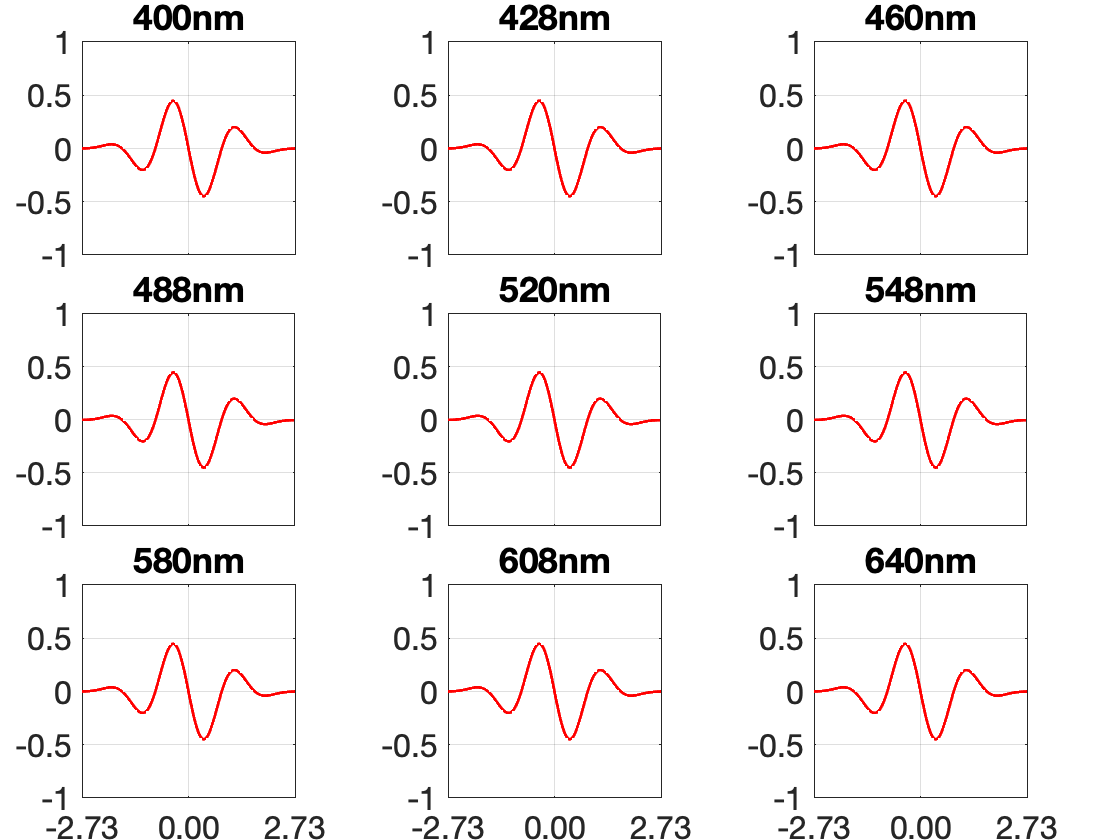

%% Compute the retinal image for the longer focal length optics
theLongerFocalLengthOI = oiCompute(theLongerFocalLengthOI, realizedStimulusScene);

%% Visualize different aspects of the computed optical image
visualizeOpticalImage(theLongerFocalLengthOI, 'displayRetinalContrastProfiles', true);

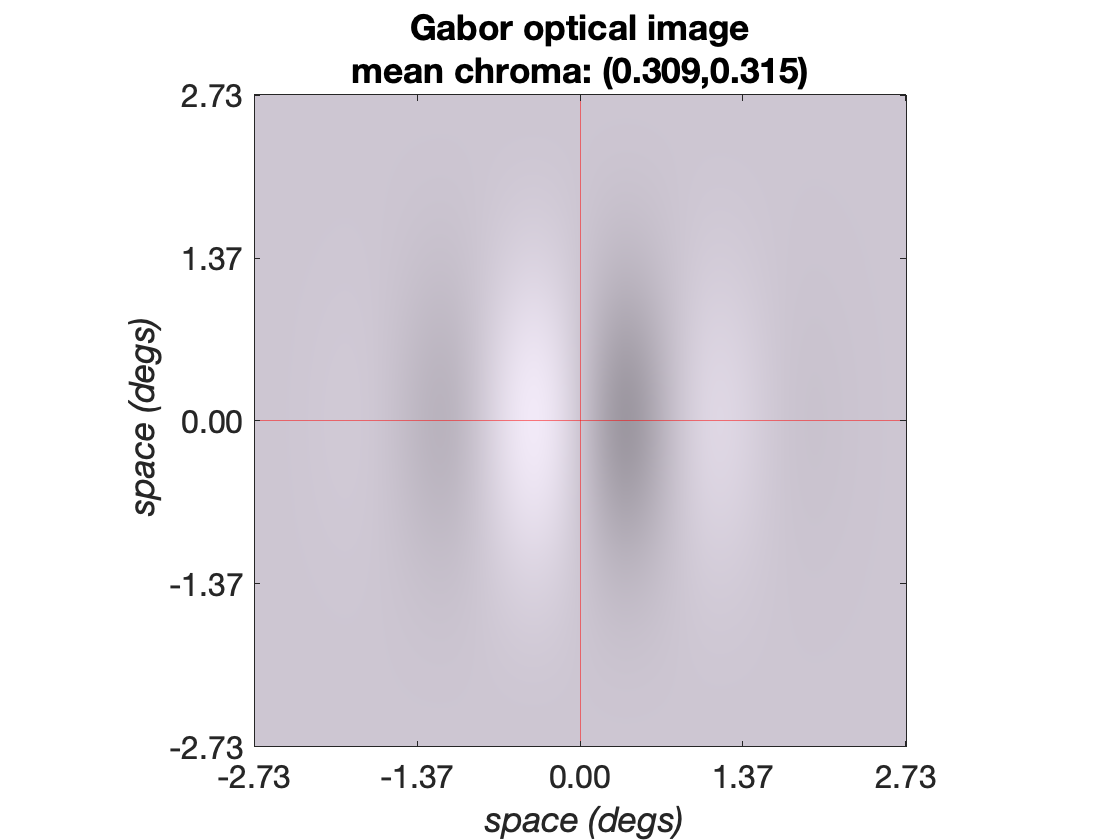

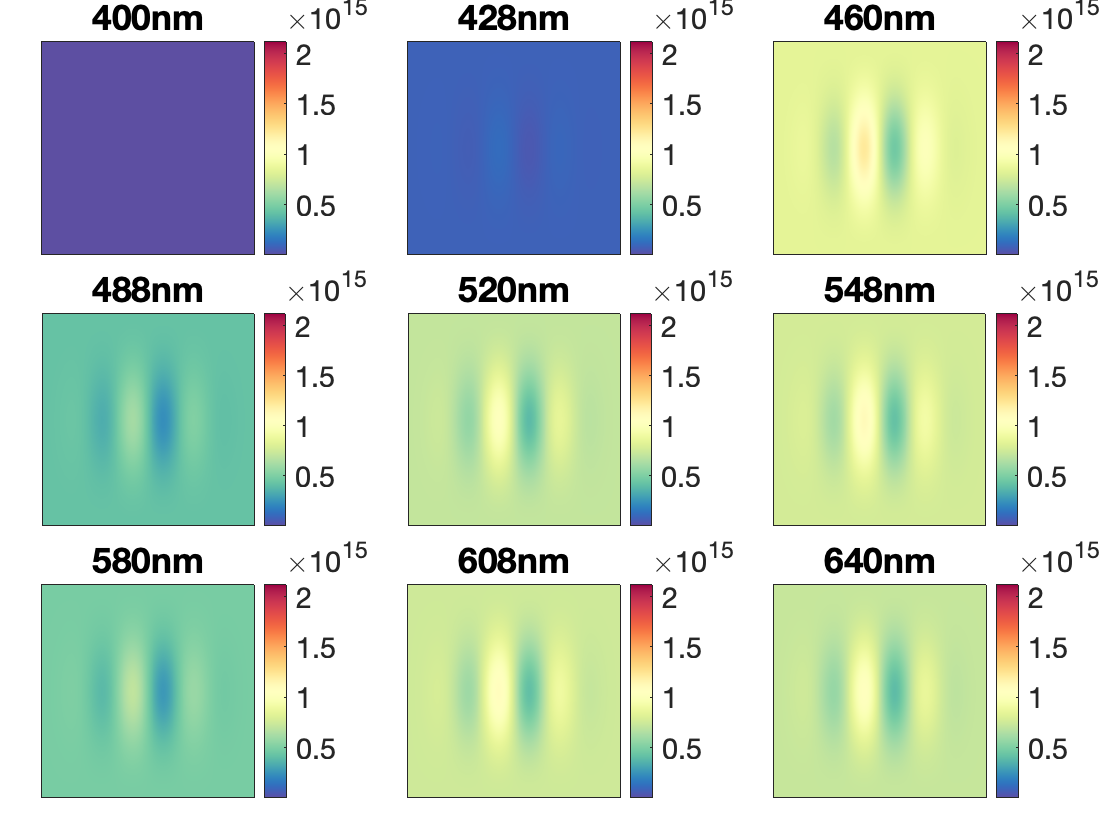

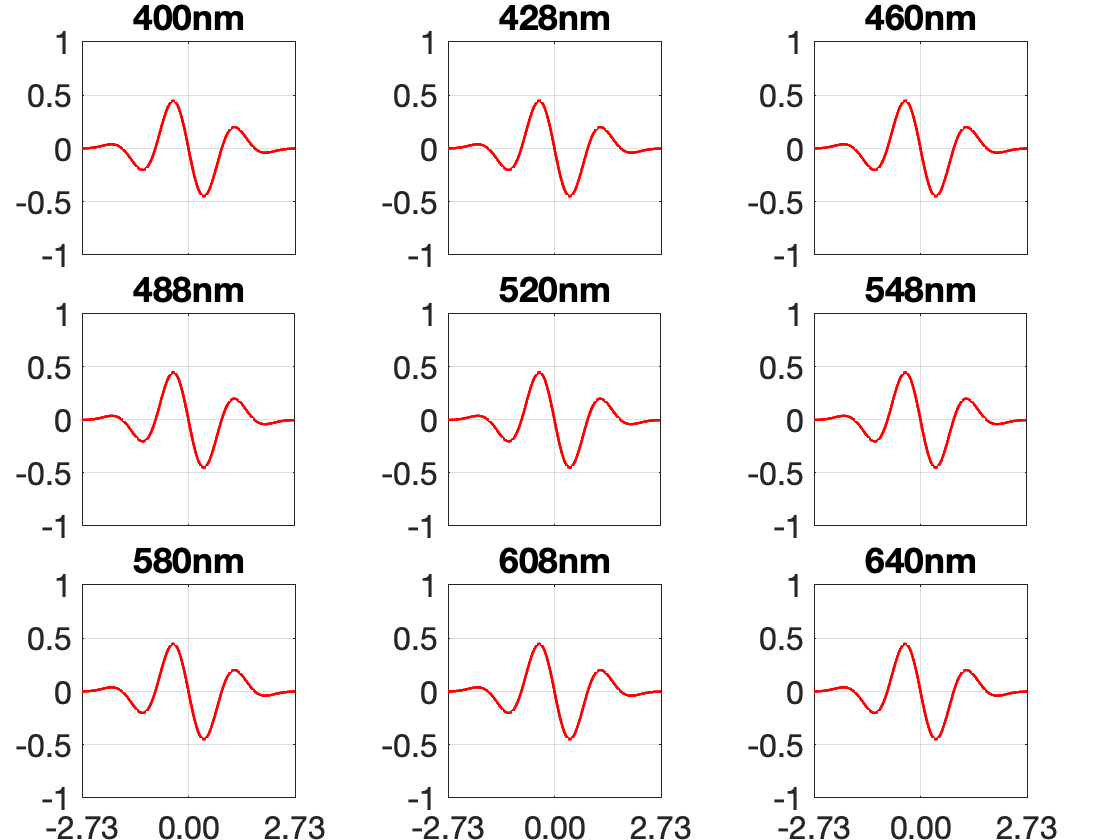

%% Compute the retinal image for the longer focal length, wider pupil optics
theLongerFocalLengthWidePupilOI = oiCompute(theLongerFocalLengthWidePupilOI, realizedStimulusScene);

%% Visualize different aspects of the computed optical image
visualizeOpticalImage(theLongerFocalLengthWidePupilOI, 'displayRetinalContrastProfiles', true);

# **Step 5.** Compare retinal illuminance levels for the different optics models

meanIlluminanceDefaultOI = oiGet(theDefaultOI, 'mean illuminance')

meanIlluminanceDefaultOI = 18.6839

meanIlluminanceBlurredOI = oiGet(theBlurredOI, 'mean illuminance')

meanIlluminanceBlurredOI = 18.6839

meanIlluminanceLongerFocalLengthOI = oiGet(theLongerFocalLengthOI, 'mean illuminance')

meanIlluminanceLongerFocalLengthOI = 4.8646

meanIlluminanceLongerFocalLengthWidePupilOI = oiGet(theLongerFocalLengthWidePupilOI, 'mean illuminance')

meanIlluminanceLongerFocalLengthWidePupilOI = 17.2719